        2518          10



     2

         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0    0.1111    0.1718    0.2251    0.2732    0.3212    0.4144    0.6096    0.8048    1.0000
         0         0         0    0.0321    0.2598    0.4876    0.5856    0.3904    0.1952         0
         0         0    0.5626         0         0         0         0         0         0         0
    1.0000    0.8889         0         0         0         0         0         0         0         0
         0         0    0.2656    0.7427    0.4670    0.1912         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0   

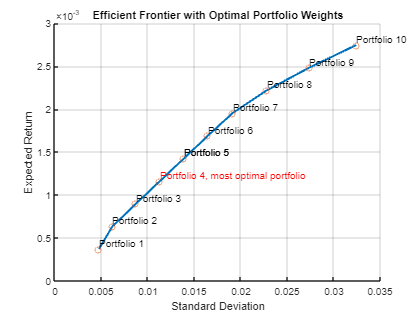

the optimal weightage for the 10 assets is
         0
         0
         0
    0.2251
    0.0321
         0
         0
    0.7427
         0
         0



     2666496



%testing area as follows:

%mkmvo(cdata,k) standard markowitz with k risk scaling factor (returns
%pwgt1 for testing)
%ssmvo(cdata,evc) returns pwgt for testing. evc is cumulative variance
%value for decomposition
%ldwmvo(cdata, delta) returns pwgt for testing, delta is shrinkage factor
%bmvo(tbd)

%clearing
clear;
clc;
close all;

k = 1; %range from 0-1, this assigns importance of risk, 1 being the highest considering the sharpe ratio

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

profile on;
memoryBefore = memory;
mkmvo(cdata, k);
memoryAfter = memory;
profile off;
profile viewer;
disp(memoryAfter.MemUsedMATLAB - memoryBefore.MemUsedMATLAB);

%test against outsample returns

%clearing
clear;
clc;
close all;

evc = 50; %this can range from 0-100 essentially encapsulating total variance (cumulative) to decide how many principal components to retain after eigendecomposition

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

profile on;
memoryBefore = memory;
ssmvo(cdata, evc);
memoryAfter = memory;
profile off;
profile viewer;
disp(memoryAfter.MemUsedMATLAB - memoryBefore.MemUsedMATLAB);
